#### Importar los datos

close all
clear all

% Abrir y decodificar el archivo json
file = 'quenan12.json';
jsonText = fileread(file); 
data = jsondecode(jsonText);

% Obtener los valores 
values = data.payload.values;

#### Graficar los datos

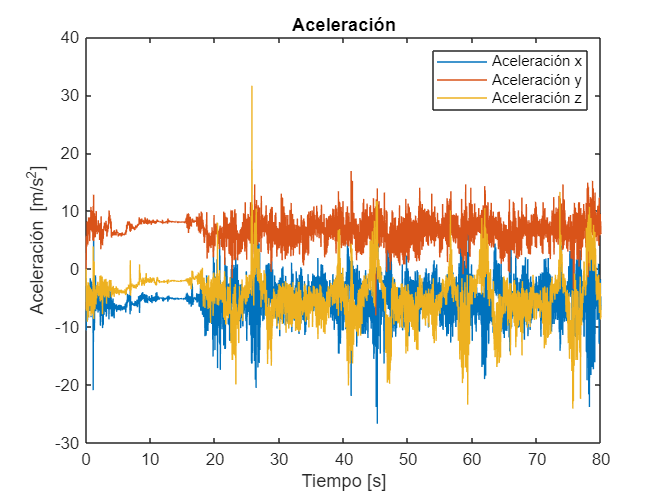

% Vector de tiempo
t = 0:1/62.5:(length(values)-1)/62.5;

% Aceleración
acc_x = values(:,1);
acc_y = values(:,2);
acc_z = values(:,3);

plot(t,acc_x)
hold on
plot(t,acc_y)
plot(t,acc_z)
xlabel("Tiempo [s]")
ylabel("Aceleración [m/s^2]")
title("Aceleración")
legend("Aceleración x","Aceleración y","Aceleración z")
hold off

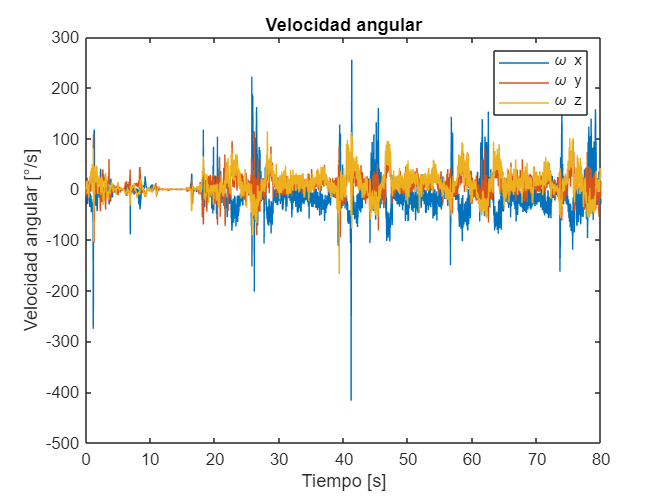


% Velocidad angular
w_x = values(:,4);
w_y = values(:,5);
w_z = values(:,6);

plot(t,w_x)
hold on
plot(t,w_y)
plot(t,w_z)
xlabel("Tiempo [s]")
ylabel("Velocidad angular [°/s]")
title("Velocidad angular")
legend("\omega x","\omega y","\omega z")
hold off

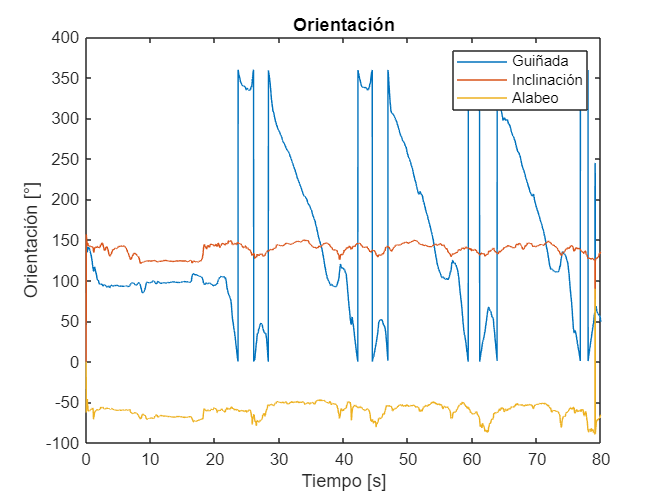


% Orientación
yaw = values(:,7);
pitch = values(:,8);
roll = values(:,9);

plot(t,yaw)
hold on
plot(t,pitch)
plot(t,roll)
xlabel("Tiempo [s]")
ylabel("Orientación [°]")
title("Orientación")
legend("Guiñada","Inclinación","Alabeo")
hold off

#### Procesar los datos

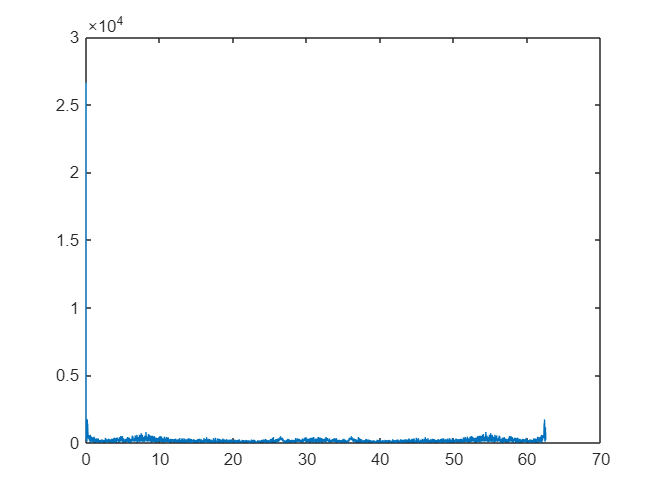

fft_ax = fft(acc_x);
fft_ay = fft(acc_y);
fft_az = fft(acc_z);

fft_wx = fft(w_x);
fft_wy = fft(w_y);
fft_wz = fft(w_z);

fft_y = fft(yaw);
fft_p = fft(pitch);
fft_r = fft(roll);

L = length(values);
plot(62.5/L*(0:L-1),abs(fft_ax)) % Magnitud

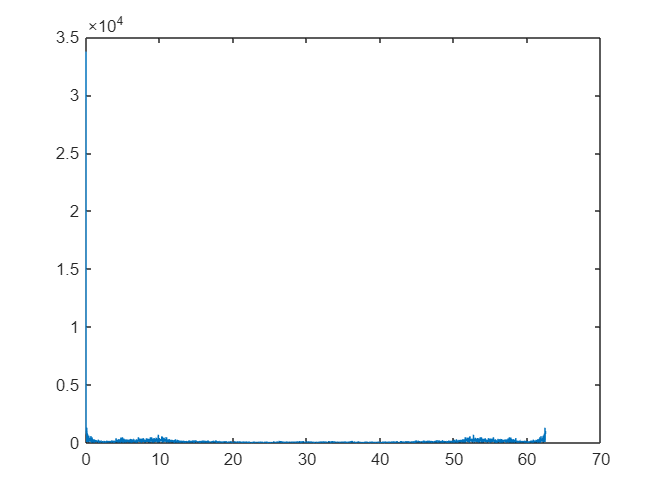

plot(62.5/L*(0:L-1),abs(fft_ay))

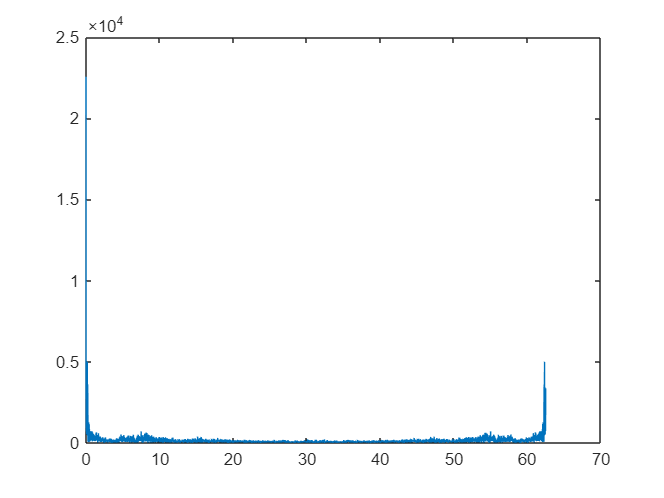

plot(62.5/L*(0:L-1),abs(fft_az))

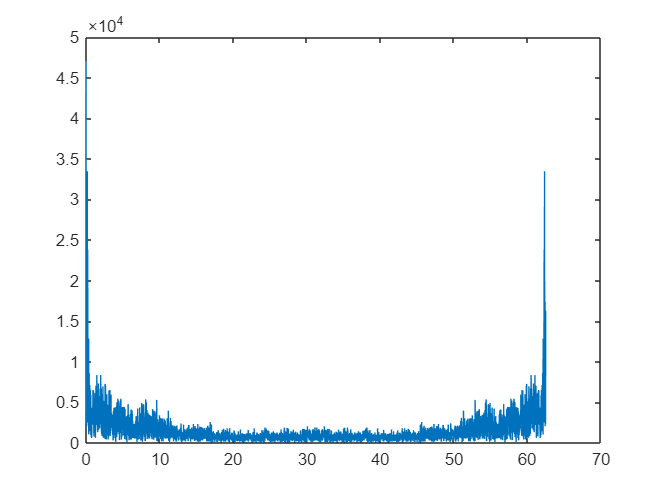


plot(62.5/L*(0:L-1),abs(fft_wx))

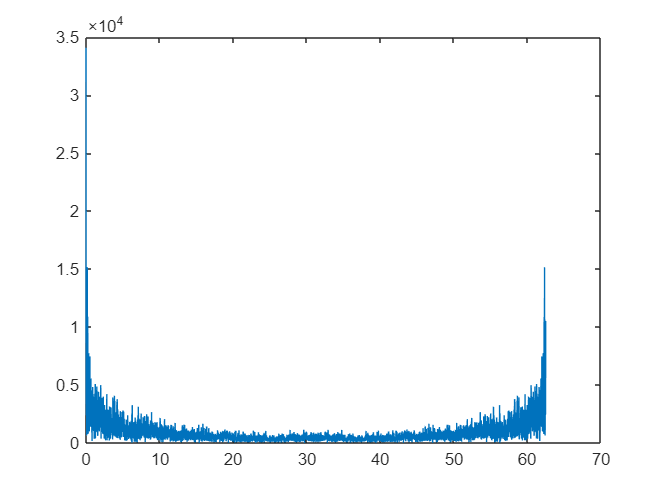

plot(62.5/L*(0:L-1),abs(fft_wy))

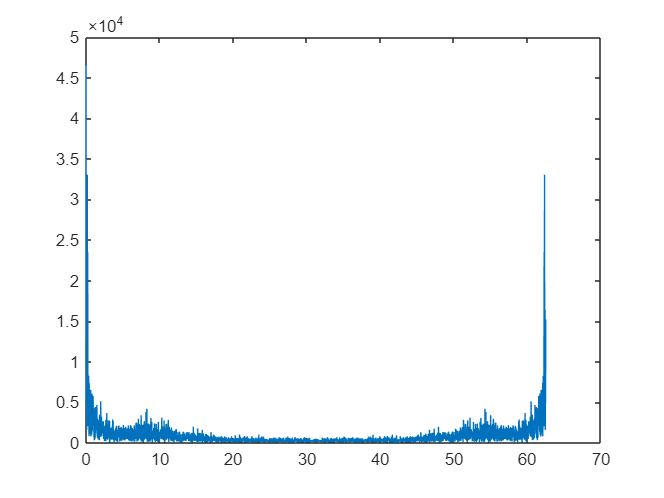

plot(62.5/L*(0:L-1),abs(fft_wz))

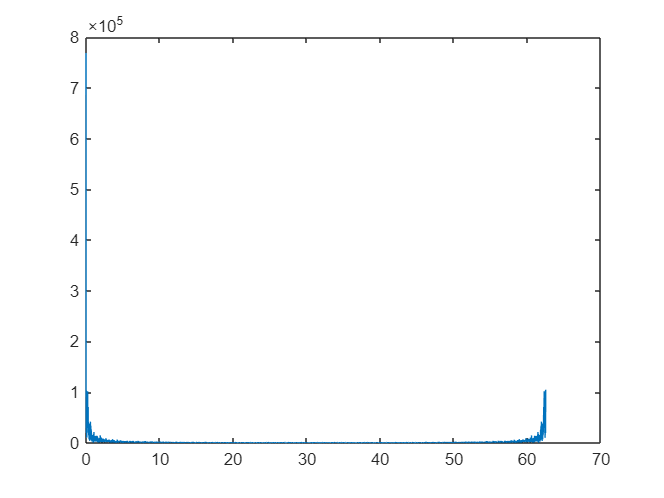


plot(62.5/L*(0:L-1),abs(fft_y))

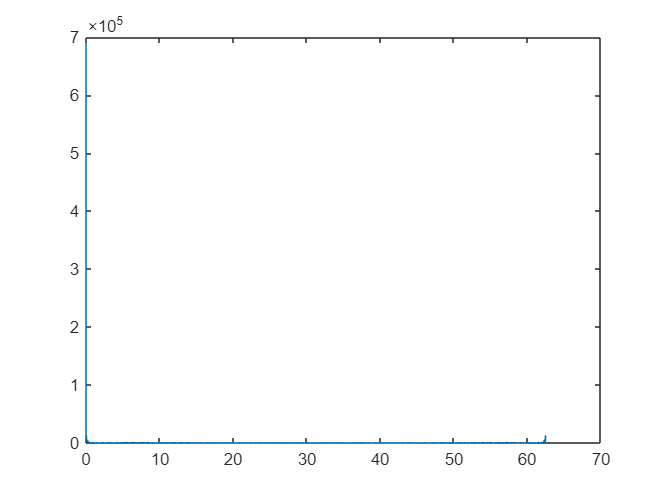

plot(62.5/L*(0:L-1),abs(fft_p))

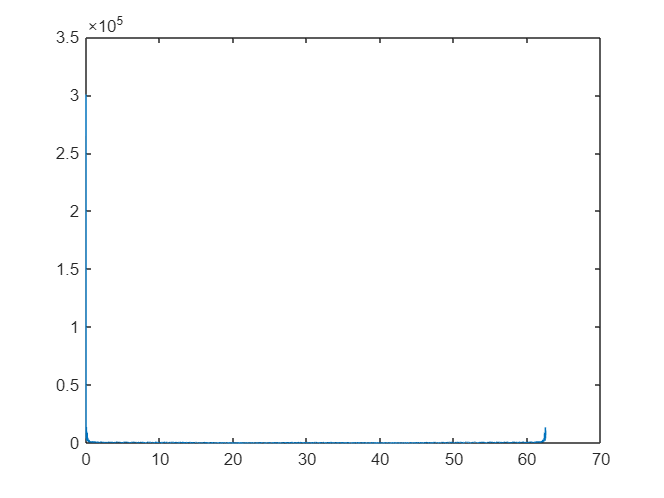

plot(62.5/L*(0:L-1),abs(fft_r))

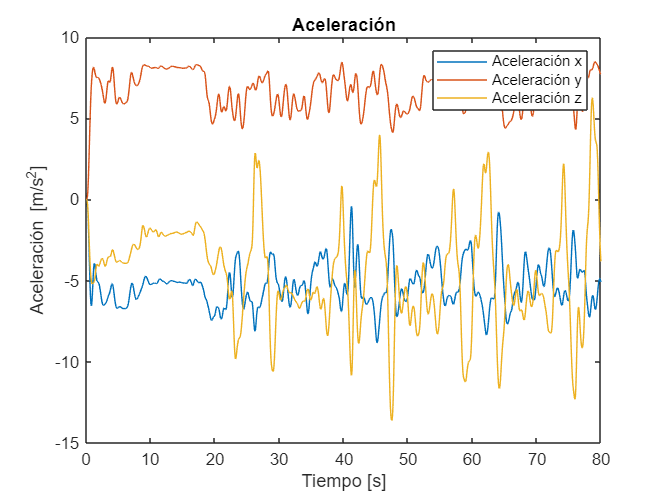

% Filtrado
cutoff1 = 1;
cutoff3 = 1;
cutoff5 = 1;
[b1,a1] = butter(4,cutoff1/(62.5/2),"low");
[b3,a3] = butter(4,cutoff3/(62.5/2),"low");
[b5,a5] = butter(4,cutoff5/(62.5/2),"low");

% Aceleración
acc_x_fil = filter(b5,a5,acc_x);
acc_y_fil = filter(b1,a1,acc_y);
acc_z_fil = filter(b1,a1,acc_z);
plot(t,acc_x_fil);
hold on
plot(t,acc_y_fil);
plot(t,acc_z_fil);
xlabel("Tiempo [s]")
ylabel("Aceleración [m/s^2]")
title("Aceleración")
legend("Aceleración x","Aceleración y","Aceleración z")
hold off

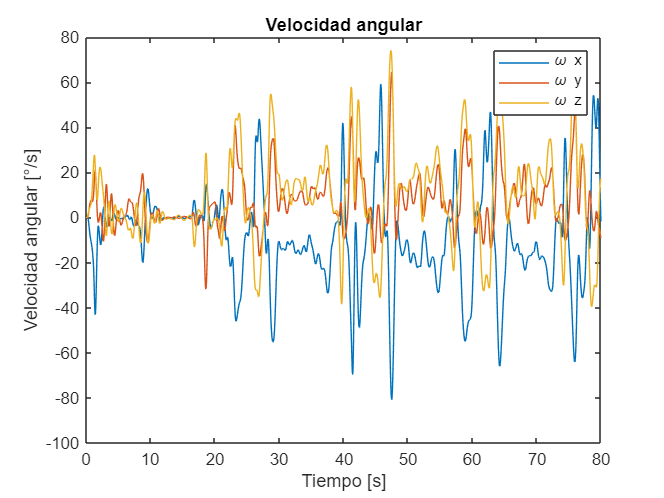

% Velocidad angular
w_x_fil = filter(b3,a3,w_x);
w_y_fil = filter(b5,a5,w_y);
w_z_fil = filter(b3,a3,w_z);

plot(t,w_x_fil)
hold on
plot(t,w_y_fil)
plot(t,w_z_fil)
xlabel("Tiempo [s]")
ylabel("Velocidad angular [°/s]")
title("Velocidad angular")
legend("\omega x","\omega y","\omega z")
hold off

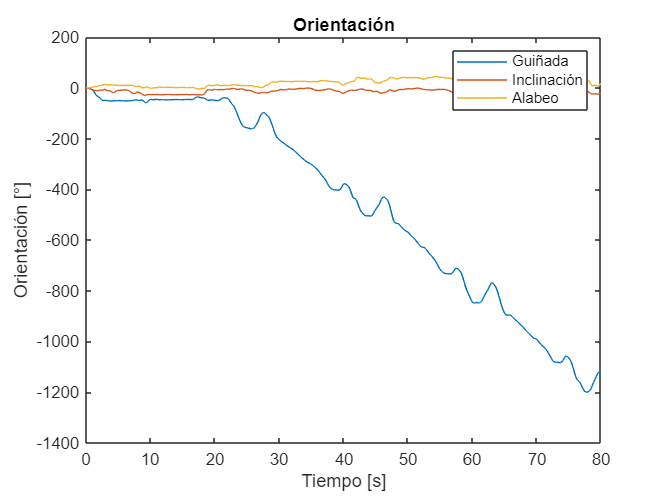

% Orientación
yaw_fil = filter(b1,a1,unwrap(yaw));
pitch_fil = filter(b1,a1,unwrap(pitch));
roll_fil = filter(b3,a3,unwrap(roll));

plot(t,yaw_fil)
hold on
plot(t,pitch_fil)
plot(t,roll_fil)
xlabel("Tiempo [s]")
ylabel("Orientación [°]")
title("Orientación")
legend("Guiñada","Inclinación","Alabeo")
hold off

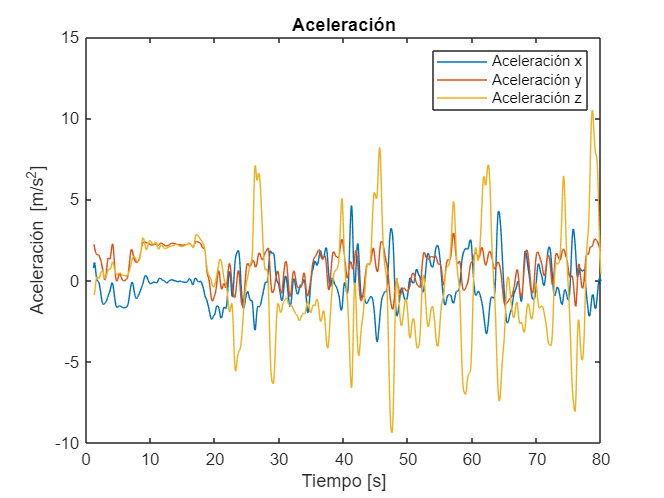

% Aceleración sin gravedad
acc_x_fil = acc_x_fil-mean(acc_x_fil(25:75));
acc_y_fil = acc_y_fil-mean(acc_y_fil(25:75));
acc_z_fil = acc_z_fil-mean(acc_z_fil(25:75));
plot(t(75:end),acc_x_fil(75:end))
hold on
plot(t(75:end),acc_y_fil(75:end))
plot(t(75:end),acc_z_fil(75:end))
xlabel("Tiempo [s]")
ylabel("Aceleración [m/s^2]")
title("Aceleración")
legend("Aceleración x","Aceleración y","Aceleración z")
hold off

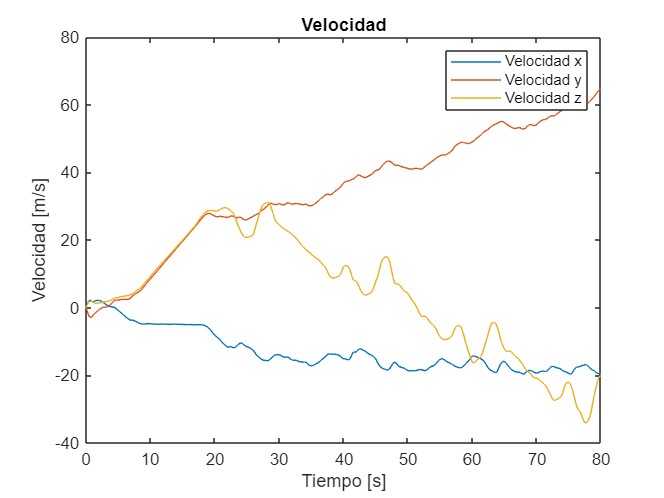

vel_x = cumtrapz(acc_x_fil)*(1/62.5);
vel_y = cumtrapz(acc_y_fil)*(1/62.5);
vel_z = cumtrapz(acc_z_fil)*(1/62.5);
plot(t,vel_x)
hold on
plot(t,vel_y)
plot(t,vel_z)
xlabel("Tiempo [s]")
ylabel("Velocidad [m/s]")
title("Velocidad")
legend("Velocidad x","Velocidad y","Velocidad z")
hold off

plot(t,deg2rad(yaw_fil))
xlabel("Tiempo [s]")
ylabel("Orientación [rad]")
title("Orientación Yaw")
hold off

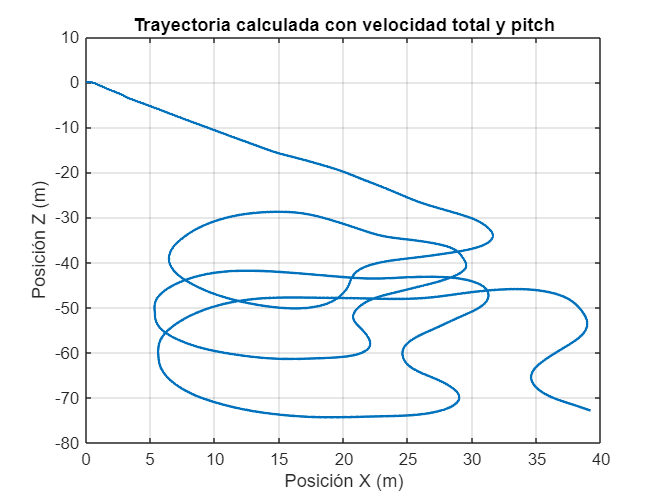

N = length(yaw_fil);
pos_x = zeros(N, 1);
pos_z = zeros(N, 1);
vel = sqrt(vel_x.^2 + vel_y.^2 + vel_z.^2);

% Calcular posiciones usando velocidad total

for i = 2:N
    pos_x(i) = pos_x(i-1) + vel(i) * cos(deg2rad(yaw_fil(i))) * (1/62.5);
    pos_z(i) = pos_z(i-1) + vel(i) * sin(deg2rad(yaw_fil(i))) * (1/62.5);
end

% Gráfica con ajuste de escala
figure;
plot(pos_x/10, pos_z/10, 'LineWidth', 1.5); 
xlabel('Posición X (m)');
ylabel('Posición Z (m)');
title('Trayectoria calculada con velocidad total y pitch');
grid on;

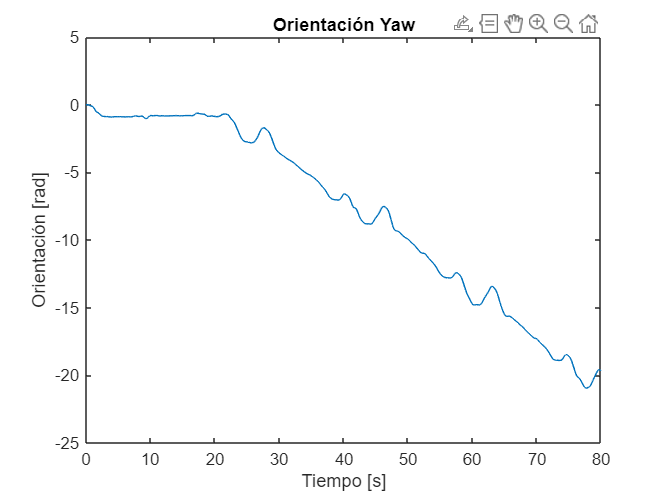


% Crear la animación
figure;
hold on;
grid on;
axis equal;
xlabel('Posición X (m)');
ylabel('Posición Z (m)');
title('Construcción de la Trayectoria');
trajectory = plot(pos_x(1), pos_z(1), 'b-', 'LineWidth', 1.5); % Línea de la trayectoria
mobile = plot(pos_x(1), pos_z(1), 'ro', 'MarkerFaceColor', 'r'); % Punto móvil

% Animar la trayectoria
for i = 1:N

    set(trajectory, 'XData', pos_x(1:i), 'YData', pos_z(1:i));

    set(mobile, 'XData', pos_x(i), 'YData', pos_z(i));

    pause(1/62.5);
end